# Part 3

In this part, we are required to compress a text file using *Huffman* codes.

First, We need to acquire the text. You can select a text file by pressing the browse button:

 
textFromFile = false;
[file , path] = uigetfile ('*.txt');

if(~file)
    disp('No file was selected.');
else
    disp(strcat("Selected file: ", file));
    originalText = fileread (strcat(path,file));
    textFromFile = true;
end

Selected file: s p a c e.txt


Selected text:

disp(originalText);

s p a c e


Our file should consist of these characters only:

charList = char(strcat(char(65:90),char(97:122), char(49:57), ",. "))

charList = 'ABCDEFGHIJKLMNOPQRSTUVWXYZabcdefghijklmnopqrstuvwxyz123456789,. '

We now extract the character data from the file and find its *Probability Mass Function, *after removing all invalid characters:

originalText(~ismember(originalText, charList)) = '';
sortedText = sort(originalText);
[labels, charPMF] = PMF(sortedText);
pmfTable = table(transpose(labels), transpose(charPMF), 'VariableNames', {'Character', 'Probability'});
disp(pmfTable)

    Character    Probability
    _________    ___________

                   0.44444  
        a          0.11111  
        c          0.11111  
        e          0.11111  
        p          0.11111  
        s          0.11111  



## Huffman Encoding

We can now use the built in function to generate a Huffman code for our file:

% The huffmandict function can't deal with the symbols as chars. We need to
% cast them into doubles.


symbols = double(labels);
dict = huffmandict(symbols, charPMF);
huffTable = cell2table(dict);
huffTable.Properties.VariableNames = {'Character', 'Codeword'};
huffTable.Character = char(huffTable.Character);

disp(huffTable)

    Character     Codeword  
    _________    ___________

                 {[      1]}
        a        {[  0 1 1]}
        c        {[  0 1 0]}
        e        {[0 0 0 1]}
        p        {[0 0 0 0]}
        s        {[  0 0 1]}



Now, we are ready to encode our text file:

encoded = huffmanenco(originalText, dict);
huffman = num2str(encoded);
huffman = strrep(huffman,' ','');
ascii = dec2bin(originalText);
ascii = reshape(ascii',1,[]);

codeTable = cell2table({ascii; huffman});
codeTable.Properties.VariableNames = {'Encoded File'};
codeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(codeTable)

                                          Encoded File                            
               ___________________________________________________________________

    ASCII      {'111001101000001110000010000011000010100000110001101000001100101'}
    Huffman    {'001100001011101010001'                                          }



We know find the compression ratio:

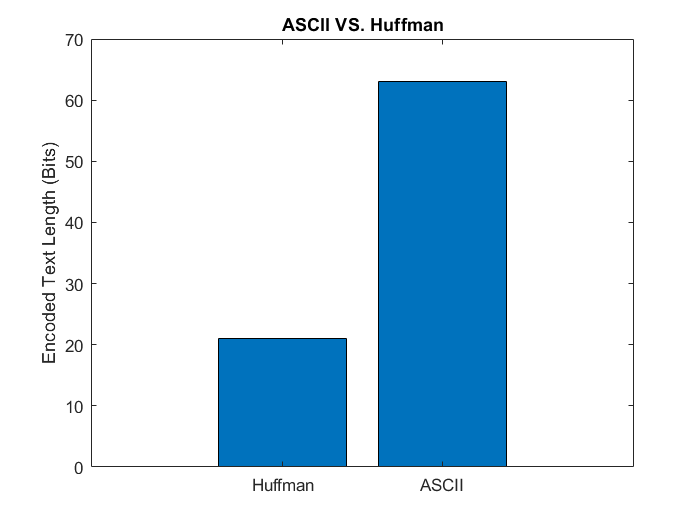

huffLen = length(huffman);
asciiLen = length(ascii);
lenArr = [huffLen asciiLen];
gra = bar(lenArr);
xticklabels({'Huffman', 'ASCII'});
title('ASCII VS. Huffman');
ylabel('Encoded Text Length (Bits)');

We can now calculate the compression ratio by applying the formula:


$$\frac{\mathrm{Length}\;\mathrm{of}\;\mathrm{Huffman}\;\mathrm{code}}{\mathrm{Length}\;\mathrm{of}\;\mathrm{ASCII}\;\mathrm{code}}\times 100%$$


% compRatio = ((asciiLen - huffLen)/asciiLen) * 100;
% fprintf("η = %f %%", compRatio)
compRatio = (huffLen / asciiLen) * 100;
fprintf("η = %f %%", compRatio)

η = 33.333333 %

## Decoding

We now decode both the ASCII and the Huffman files to check for errors. We expect none due to the one-to-one mapping in both ASCII and Huffman:

decodedHuff = char(huffmandeco(encoded, dict));
decodedASCII = zeros(1, asciiLen);

for i = 1:7:asciiLen-6
    % We need to decode each 7 bits into a single character
    
    letterBits = extractBetween(ascii, i, i+6);
    
    letter = char(bin2dec(letterBits));
    if letter == ' '
        decodedASCII = strcat(decodedASCII," ");
    else
        decodedASCII = strcat(decodedASCII, letter);
    end
    
end


decodeTable = cell2table({decodedASCII; decodedHuff});
decodeTable.Properties.VariableNames = {'Decoded File'};
decodeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(decodeTable);

               Decoded File
               ____________

    ASCII      "s p a c e" 
    Huffman    "s p a c e" 




% And now, we compare the decoded text with the original text:

if(strcmp(decodedHuff, originalText))
    disp("Huffman codes are error free as expected.")
end

Huffman codes are error free as expected.



if(strcmp(decodedASCII, originalText))
    disp("ASCII codes are error free as expected.")
end

ASCII codes are error free as expected.


We now output the Huffman decoded file for further inspection:

 
fid = fopen(strcat(path,"huffman.txt"),'w+');
fprintf(fid, decodedHuff);
fclose(fid);

## Comments

- Huffman coding is a lossless coding method, which by definition means it's error free.

- ASCII codes are made for computers to represent text, not for compression. We have 64 characters in our character list, which means we need only $\log_2 \left(64\right)=6\;\textrm{Bits}$ to represent each charachter, not $7\;\textrm{Bits}$.

## Functions

function  [uniqueChars, pmfCharArr] = PMF(text)
            % Returns the probability of each charachter in an array
            
            textLen = length(text);
            uniqueChars = unique(text);
            uniques = length(uniqueChars);
            pmfCharArr = zeros(1, uniques);
            
            for idx = 1:uniques
                pmfCharArr(idx) = sum(text == uniqueChars(idx)) / textLen ;
            end
 end